# **Pixel-wise image processing operations**

## **Objetives**

This work focuses on elementary operation on pixel values: mappings, quantization and histograms. The “Image processing” and “Communication” toolboxes of matlab is necessary for this work. Note also that some matlab functions (*.m files) are included in this folder. They should be accessible by matlab (either by using the folder as current matlab directory or by including the folder in matlab path).

In this practice (and the following ones) it is recommended to execute it section by section (button: "Run Section") within the Matlab Live Editor environment (pressing the button is indicated with a yellow box in the following figures depending on the version of Matlab being used):

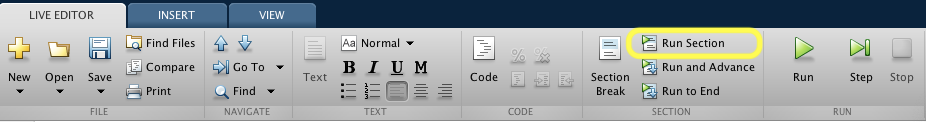

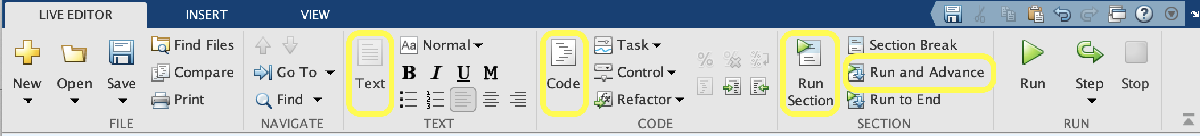

This figure shows the location of the buttons to format the text as such, or as code, as well as the buttons that lead to the execution of the code: "Run Section" and "Run Section and Advance". As always, we have to go to the working directory.

pwd     % Shows the current working directory

ans = 'C:\Users\ismai\Desktop\MATT\DIVP\Homework1_Live'

## **1.- Mappings s=T(r)**

We selected the image from Google. We are going to play with the range of gray level values with mapping. 

Read it in Matlab so that you can process it. The basic Matlab command to read images is: 

ima_ori= imread('lena.png');  

We want to work with gray level images. So, if your image is a color image, convert it to a gray level image, for example using the following command (See the help for alternative commands).

% Execute this line if you need to convert the image to gray
ima_gray=rgb2gray(ima_ori);  

% Otherwise just execute the following command
% ima_gray=ima_ori;  

Finally, normalize the image gray level values between 0 and 1. 

ima=double(ima_gray)/255;  

We start using the function *READ_IMAGES* to display the image. 

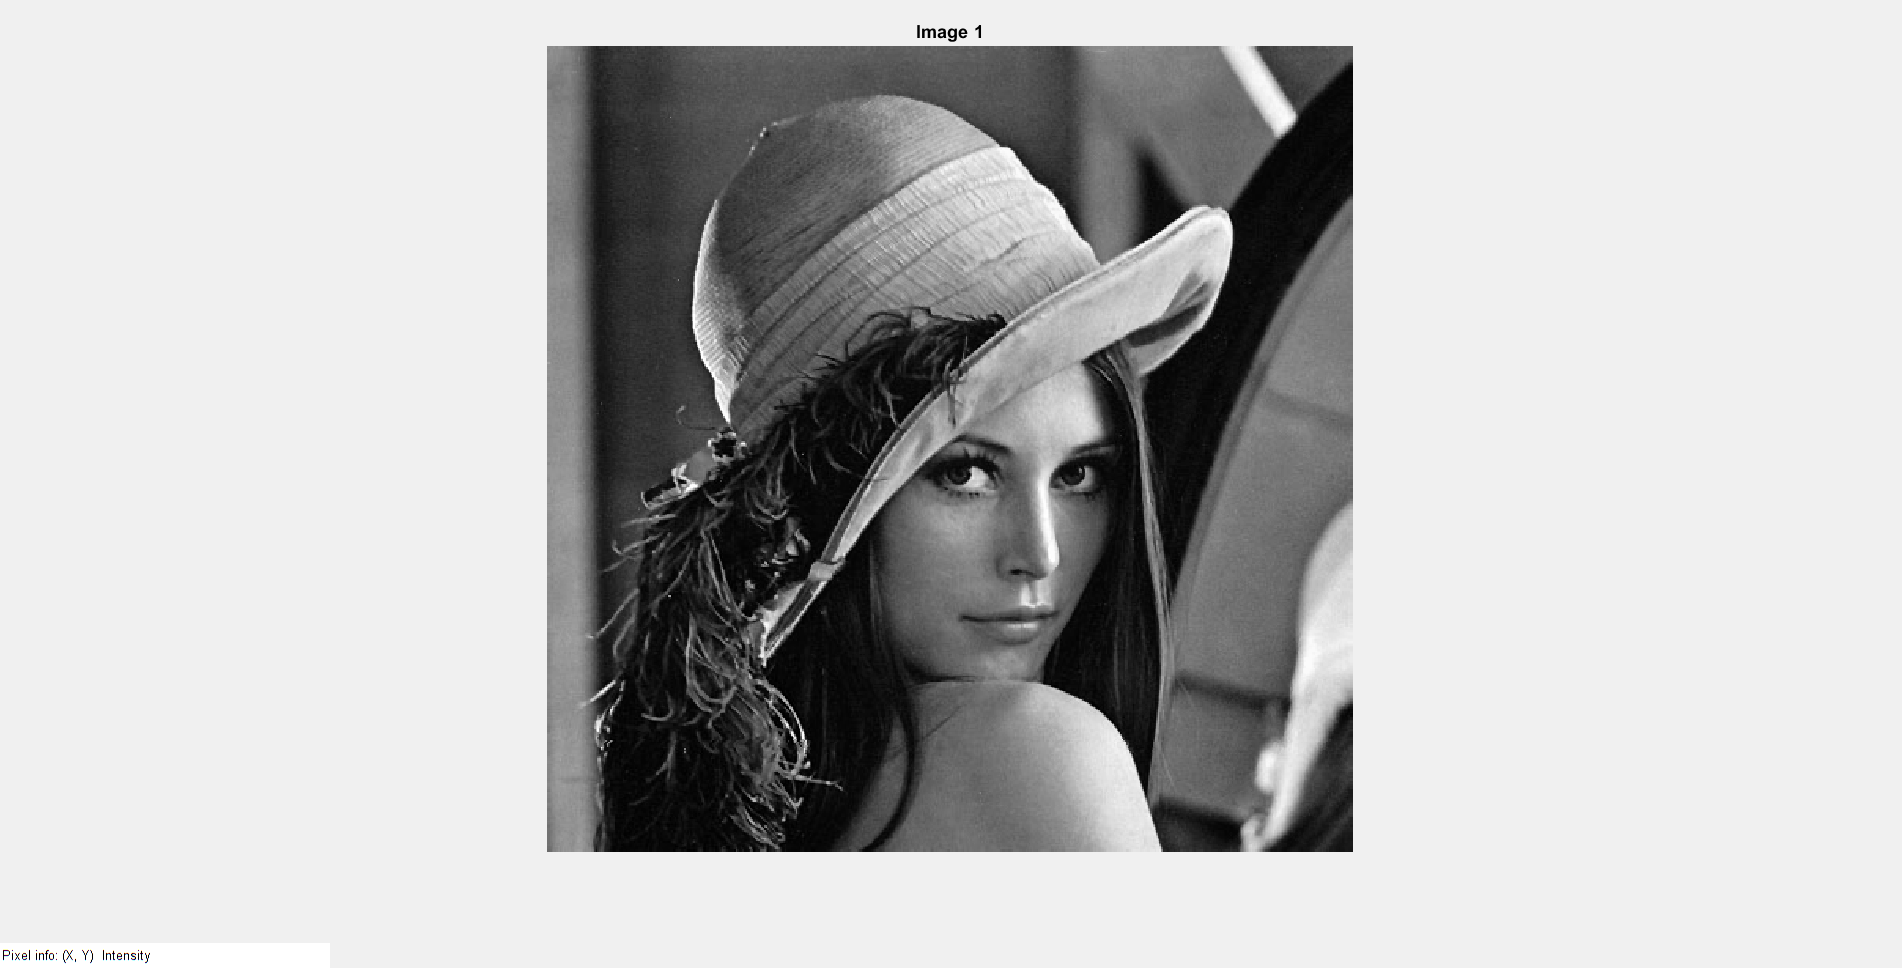

Display_Images(ima);

### 1.1.- Lineal contrast

The function

***    J ****= Contrast *(***I****, *[*bajo alto*]*, *[*min max*])

maps the luminance values of image ***I*** between the *darkest *value (*low*: close to 0.0) and the *brightest *value(*high*: close to 1.0) between *min* and *max* in the output image **J**. Values below *low* (resp. above *high*) map to *min* (resp. *max*).

Let's increase the contrast of the image with this function. And also try to execute different contrast levels.

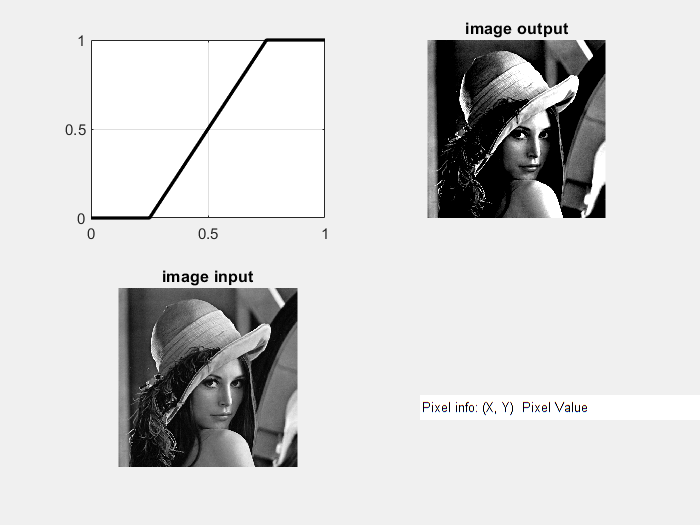

ima2 = Contrast(ima, [0.25 0.75], [0.0 1.0]);  

Observe the clipping of values above 0.75 (resp., below 0.25). All these values will be mapped to the maximum (resp. minimum) brightness.

Modify the input range [*low high*] and output range [*min max*] in the function *CONTRAST*() in order to get the mappings requested below. To do so, just uncomment and complete the MATLAB command below and change [*low high*] and [*min max*] adequately. Execute the command in matlab and comment the observed effect. 

1.  Contrast reduction

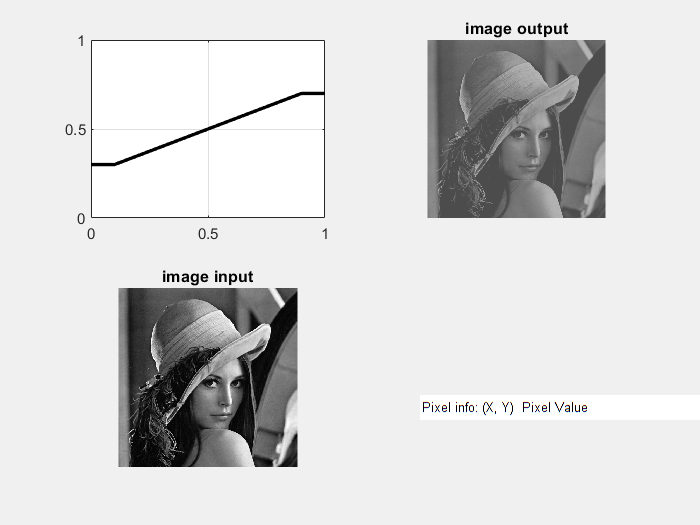

ima2 = Contrast(ima, [ 0.1,0.9 ], [0.3 ,0.7 ]);

- Comments:

- The input range is now mapped to a narrower output range. This reduces the overall contrast.

- By using the `Contrast` function with the adjusted ranges `[0.1 0.9]` and mapping to `[0.3 0.7]`, the overall contrast of the image is reduced. As a result, the image appears less defined, with fewer differences between dark and bright areas. 

2. Inversion of the range of grey levels of the image (negative image)

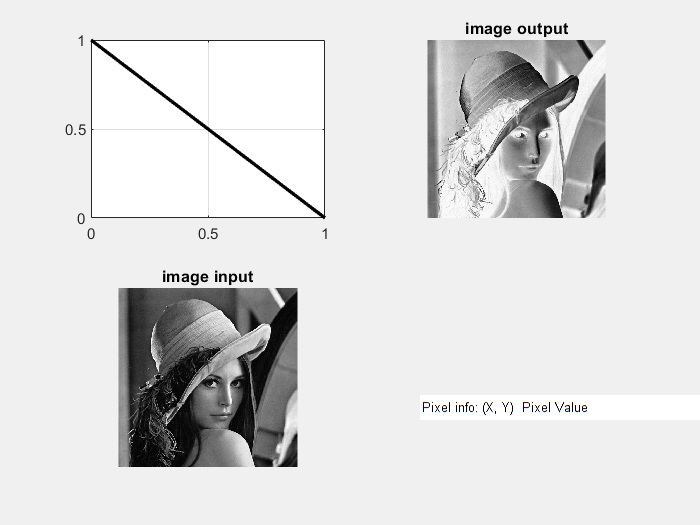

ima3 = Contrast(ima, [ 0,1 ], [ 1,0 ]);

- Comments:

-  This mapping inverts the grey levels of the image.

3. Expansion of a limited range values. Select a range of value from x1 to x2 where something meaningful appears in your image but that are difficult to observe and expand this range of value so that they occupy the full range (from 0.0 to 1.0)

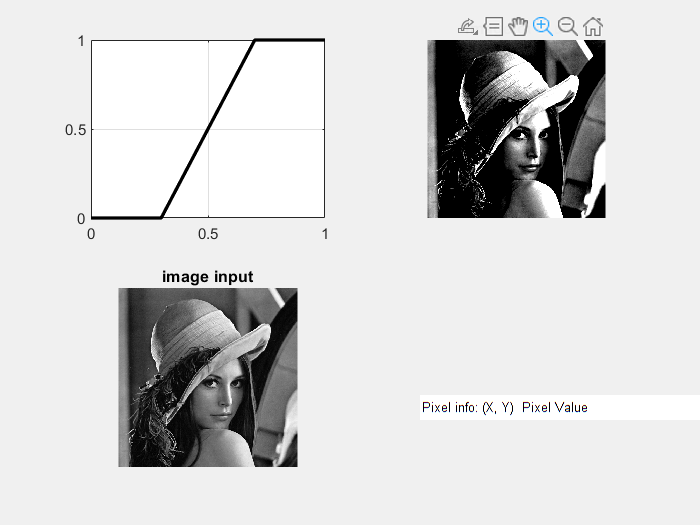

ima2 = Contrast(ima, [0.3 ,0.7 ], [0,1]);

- Comments:

-  This makes details within that range much clearer and more pronounced.

-  Previously hard-to-see content becomes much more visible, as the pixel values within this range are stretched to fill the full contrast spectrum.q

4. Binarizing the image with a threshold of 0.5. Doing this with the *CONTRAST*() function requires some degree of creativity. A hint: the original image has its luminance range (from 0.0 to 1.0) uniformly quantized with 256 gray levels. We used the following command: "ima=double(ima_gray)/255;" 

Try to obtain the best [*low high*] and [*min max*] parameters to ensure that the output image is binary (only two output values) for an arbitrary input image.

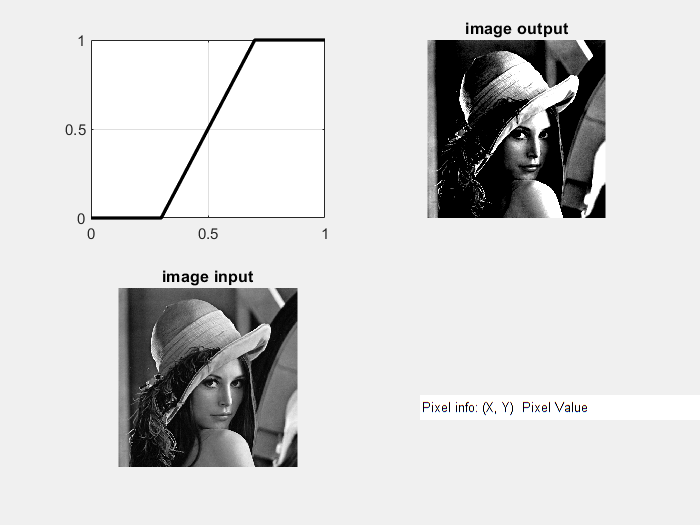

ima2 = Contrast(ima, [ 0.4999 , 0.5001 ], [0 , 1]);

- Comments:

-  This allows us to binarize the image with a threshold at `0.5`

- This results in an image where all pixels below the threshold are set to `0` (black), and all pixels above are set to `1` (white), creating a binary image.

###  **1.2.- ***Non-linear contrast: gamma*

The function *CONTRAST*() allows adding a last argument, *gamma*, in order to obtain non-linear mappings as in the figure below:

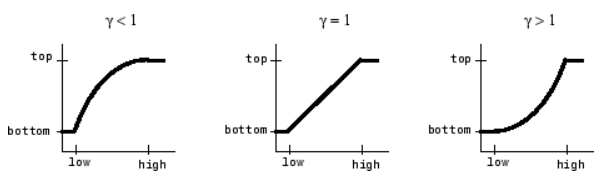

The complete syntax of the contrast function is: 

*ima3=**Contrast*(*ima, *[*low high*]*, *[*min max*]*, ****gamma***);

Use this command with the appropriate [*low high*], [*min max*] and gamma value with one value of gamma below 1.0 and one above 1.0. Let us start with the gamma value below one.

gamma = 0.5; % Uncomment and Define a gamma value below 1.0 
ima3 = Contrast (ima, [ 0.3 ,0.7], [0,1 ], gamma);

Describe the visual effect of the mapping.

- Comment:

- **Gamma < 1.0**: This enhances the **darker regions** of the image. The image will appear brighter overall as more emphasis is placed on the darker values.

- **Gamma > 1.0**: This enhances the **brighter regions** and makes the image appear darker overall as more emphasis is placed on the bright values.

- The pixel values in the selected range `[0.3, 0.7]` are adjusted in a non-linear fashion, with lower values boosted more significantly.

Let us work with a gamma value above one.

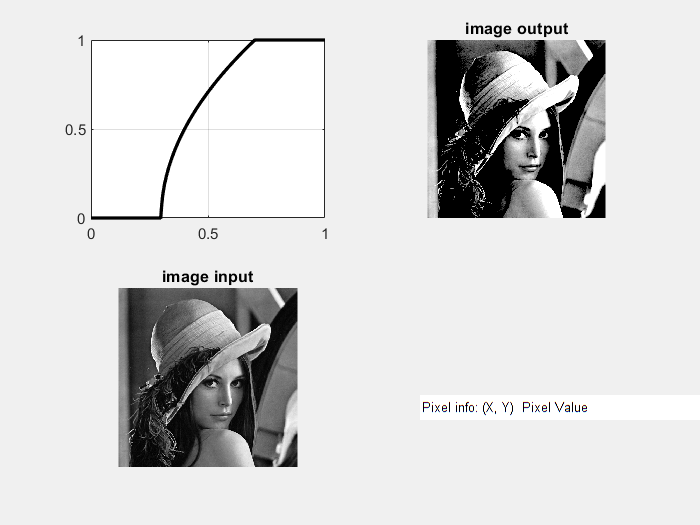

gamma =  2.0; % Uncomment and Define a gamma value above 1.0 
ima3 = Contrast (ima, [ 0.3,0.7], [0,1 ], gamma);

Describe the visual effect of the mapping.

- Comment:

- This will cause the brighter regions to be enhanced while compressing the darker regions, making the image appear **darker overall**.

- The non-linear contrast adjustment makes the bright areas more pronounced, while the overall image appears darker due to the suppression of the lower intensity values. 

Closing any open MATLAB Figure in order to free some memory.

close all

## 2.- Histogram

### **2.1.- The Histogram() function**

The histogram computes the relative frequency of the different gray levels of a given image. 

Use the function *HISTOGRAM*() to show the histograms of *ima*, *ima2 *(the binarized image) and *ima3 *(the last image produced with the gamma correction). Explain the results you get depending on the mapping used before.

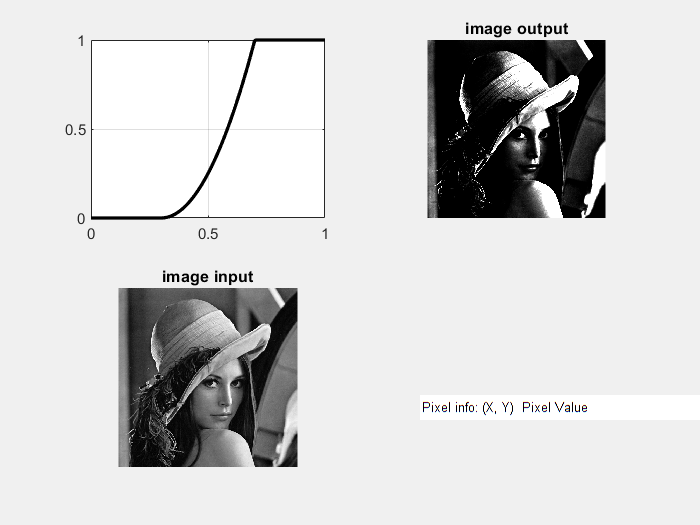

Histogram(ima,ima2,ima3);

- Coments:

-    The original image has a **natural gray level distribution**, so the histogram will reflect this, showing a variety of intensity values with no extreme contrast modifications.

- The histogram of the binaried image will have more constant values because the binarization process maps all pixel values below a certain threshold to 0 and all values above the threshold to 1.

- Gamma correction introduces non-linear transformation of pixel values, either emphasizing the darker regions (gamma > 1.0) or the brighter regions (gamma < 1.0). So in the histogram plot for gamma <1.0 more values are on the bright end and otherwise, more values are on the dark end.

### 2.2.- *Entropy of an image*

The zero-order entropy of an image is a statistic measure related to the distribution of gray levels in the image. It is noted as *H, in bits/pixel*. Entropy can be approximated using the image histogram *h(r**k**)* as follows (*r**k*are the discrete gray levels):

Compute the entropy of images *ima, ima2* and *ima3* using the *ENTROPY*() function:

Entropy(ima)  
Entropy(ima2)  
Entropy(ima3)  

Could you comment and explain the absolute entropy values (what values were you expecting in each case) as well as the difference in entropy values for these images?

The image ima has **significant variation** in its intensity levels, meaning it contains a lot of detail and complexity. This corresponds to higher entropy value.

The image ima2 the information content is much reduced. So the entropy value will be less than the image ima. However, the entropy is not extremely low (like 0 or 1) because there is still a relative distribution of pixels between the two states (black and white), and the proportions of these two levels can vary across the image.

The gamma correction process introduces a **non-linear mapping**, either compressing or expanding certain ranges of gray levels (depending on the gamma value).

"The gamma-corrected image (`ima3`) has the lowest entropy value of `4.0840` bits/pixel. This reduction occurs because the non-linear gamma correction reduces the variety of gray levels, compressing either the darker or brighter areas depending on the gamma value used. 

### 2.3.- *Discret**e equalization*

The function *EQUALIZE_HISTOGRAM()* equalizes the histogram of a digital image. We will use this function to equalize the histogram of an image. You may use the same image as in the previous section or select a different one.  Here again try to think about the goal of image equalization and select an appropriate image. 

First visualize the image histogram:

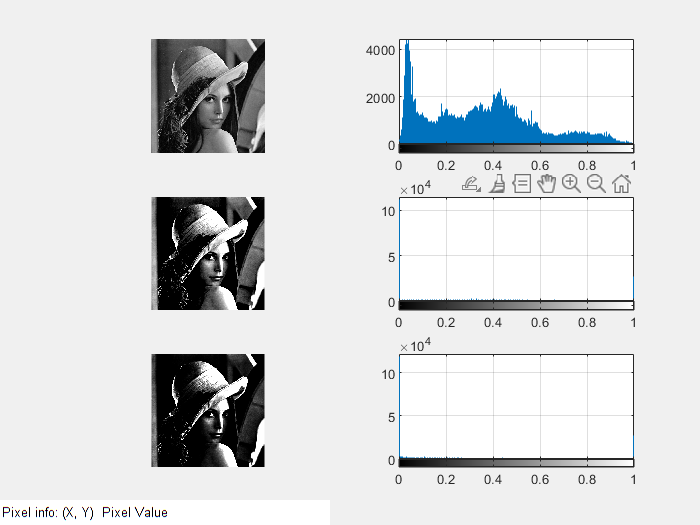

Histogram(ima);  

Next, we equalize its histogram:

ima_eq= Equalize_Histogram(ima);  

ans = 7.6296

and display the result:

Histogram(ima, ima_eq);   

ans = 4.3739

Comment the main differences between the original and equalized images. What are the main advantages and drawbacks of this transform? 

- The original image may have poor contrast, with many pixel values clustered in a narrow range (either through the dark or bright end)

- After equalization the image will have enhanced contrast, making it easy to see the details that were previously hidden in either the shadows or highlights.

- The advantages of histogram equalization are:

- 1- Enhanced contrast

- 2- Wider range of gray levels

- 3- Improved visual quality

- Drawbacks:

- 1- Noise amplification: In areas with low signal variation (like flat, smooth regions of the image), histogram equalization can **amplify noise** and make it more noticeable.

- 2- Loss of detail of the image: While contrast is improved overall, certain regions that were already well-contrasted may lose some detail after equalization, as pixel values get redistributed.

- 3- Over-enhancement of some areas

Is it possible to perfectly equalize a digital image? Why?

- No it is not possible becuase of these reasons

- 1- Discrete Nature of Digital Images:

- 2- Non-uniform Initial Distribution: Most of the images have a non-uniform distribution of pixel intensities. Some intensity levels might be more dominant than others. When applying histogram equalization, the algorithm attempts to redistribute the intensity values, but it can't always evenly spread out pixel values across all gray levels due to these initial imbalances.

-  3- Integer Quantization: After histogram equalization, pixel values must still be quantized to integers (for example, 0 to 255 in an 8-bit image). Since pixel intensities are integers, the process can't perfectly assign exactly equal numbers of pixels to each gray level.

## 3.- N-level Quantizer

In this section, we will design a uniform quantizer and an optimum quantizer adapted to the values of the image to be quantized. You may use the same image as in the previous section or select a different one.

### 3.1.- *Uniform **Quantizer*

As previously mentioned, your image is stored in memory as a matrix of floats. The obvious way to quantize an image is by truncating the matrix to integer values. We can use the MATLAB function *round*(), which rounds float values to the nearest integer. However, given that image values are in the range 0.0 to 1.0, we need to scale it by multiplying by a fixed amount before applying *round*(). Quantize your image: 

 ima_quant=round(255*ima)/255;

ans = 4.0840

 ima_quant1=round(50*ima)/50;
 ima_quant2=round(10*ima)/10;  

How many discrete gray levels these quantized images will have? Observe that we have restored the quantized values image back to the [0.0 1.0] range

- Comments: 

- `ima_quant`: With 256 gray levels, this image will closely resemble the original, retaining most of the image's details and smooth gradients.

- `ima_quant1`: With 51 gray levels, some detail will be lost, and the image may begin to exhibit noticeable quantization effects, especially in regions with subtle gradients.

- `ima_quant2`: With only 11 gray levels, the image will show significant posterization, with abrupt transitions between intensity levels, resulting in a highly simplified image.

*DISPLAY_IMAGES*(),  allows us to visualize several images simultaneously, and normalizes each one of them separately. 

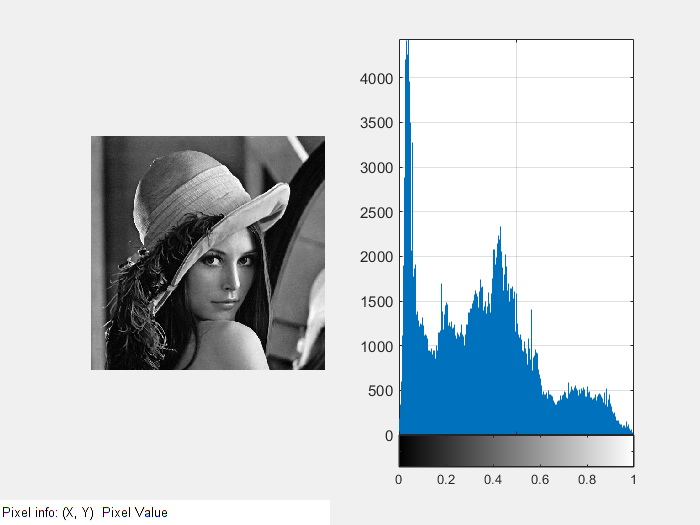

Display_Images(ima_quant, ima_quant1, ima_quant2);  

Observe the effect of "false contours" appearing in the images quantized with too few gray levels.

From the previous experiment, we define the function *uniform_quantizer*():

`function output_image= uniform_quantizer(input_image, N);`

`%`     `UNIFORM QUANTIZER with N levels`

`%`     

`%`     `output_image=uniform_quanizer(input_image, N)`  

`%`     `quantizes a float valued image input_image `

`% with N uniform discrete levels`

`%`

`% DIVP, Sep05`

`if (N>1)`

`output_image = round((N-1)*input_image)/(N-1);`

`else`

      `error('The number of gray levels requested should be greater than 1');`

`end`

`return`  

The text above is actually the code of the function *Uniform_Quantizer.m*. Check that MATLAB has access to this function by typing the following command:

help Uniform_Quantizer   

You can use the function *uniform_quantizer*() to experiment with quantization levels. Change N in the expression below and execute the command:

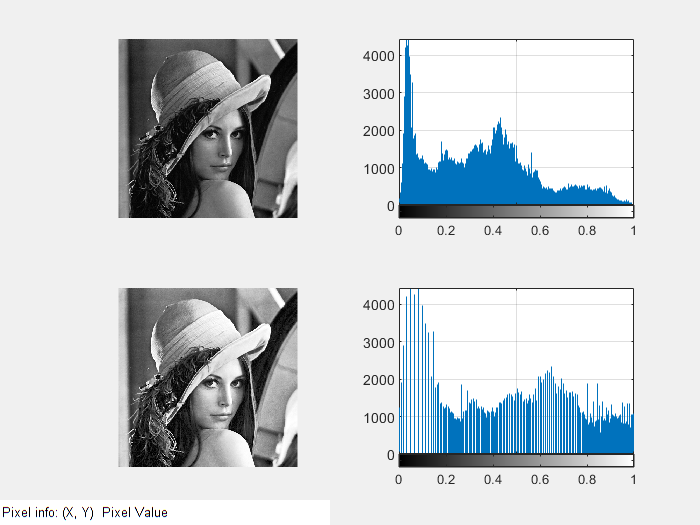

N = 2 % Uncomment and define N

ima_quant3=Uniform_Quantizer(ima, N );  
Display_Images(ima_quant, ima_quant3);  

Determine the number of gray levels N (approximated to: +/-10) so that the quantization is not visible to the naked eye.

- Answer:The number of gray levels where quantization is not visible to the naked eye is typically around **N = 128** or higher.

Binarize the image using *uniform_quantizer*()

- Answer: The image can be binarized by setting `N = 2` in the `Uniform_Quantizer()` function.

In this last experiment, have you observed what is the actual threshold level that is used to binarize the image? In the case N=2, could you suggest some changes in the expression `round(1*im_ent)/1 ``so that we can set the `binarization `threshold level to any arbitrary value 0.0<``k``<1.0? `

- modified expression: ima_bin = double(ima >= k);

Image entropy, in bits/pixel, is a measure of cost of coding the image according to the occurrence probabilities of the gray level values of the pixels. 

Of course, any image with just a few different gray level values can be coded with fewer bits per pixel. Check the entropy values with the images you have previously quantized:

Entropy(ima_quant1)  
Entropy(ima_quant2) 
Entropy(ima_quant3) 

Are these the entropy values you were expecting`?`

- Comments: 

- **If **`N`** is high** (e.g., close to 256), the entropy would be higher. **If **`N`** is high** (e.g., close to 256), the entropy would be higher

-  The entropy values for `ima_quant1`, `ima_quant2`, and `ima_quant3` should be **progressively lower** as the number of gray levels decreases. This is because quantization reduces the number of distinct pixel values in the image, leading to less variability and a more predictable (lower entropy) image.

### 3.2.- *Quantization error*

The quantization error can be measured with the mean squared error (approximated by the function *MSE_IMAGE()*) and the peak-signal-to-noise ratio with *PSNR_IMAGE()*:

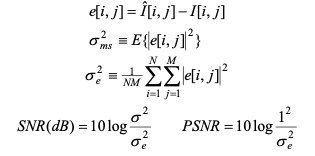

Compute these values for your quantized images 

mse_image(ima,ima_quant2)  
psnr_image(ima,ima_quant2)  
ssim(ima,ima_quant2)  

mse_image(ima,ima_quant3)  
psnr_image(ima,ima_quant3)  
ssim(ima,ima_quant3)  

Comment these values`:`

- Comments:

- **MSE (Mean Squared Error)**: Measures the average squared difference between the original image and the quantized image.

- **PSNR (Peak Signal-to-Noise Ratio)**: Measures the ratio between the maximum possible power of a signal (the image) and the power of corrupting noise (quantization errors). A higher PSNR generally indicates better quality.

- **SSIM (Structural Similarity Index)**: Compares the structural similarity between two images. A value close to 1 indicates high similarity, while values closer to 0 indicate significant structural differences.

The **MSE** should be **higher** for `ima_quant2. `**PSNR** will be **lower** for `ima_quant2, `**SSIM** for `ima_quant2` should be **relatively low**

 The **MSE** for `ima_quant3` depends on the value of `N` you choose. If `N` is closer to 256 (fine quantization), the MSE will be lower. However, if `N` is smaller, the MSE will increase. In general, as `N` decreases, MSE increases because the quantization introduces more rounding errors.

**SSIM** for `ima_quant3` will be **closer to 1** (high similarity) for larger values of `N`

### **3.3.- ***Optimum Quantizer*

Let us now compare uniform quantization with the optimum Max_Lloyd algorithm. Define a given number of level N:

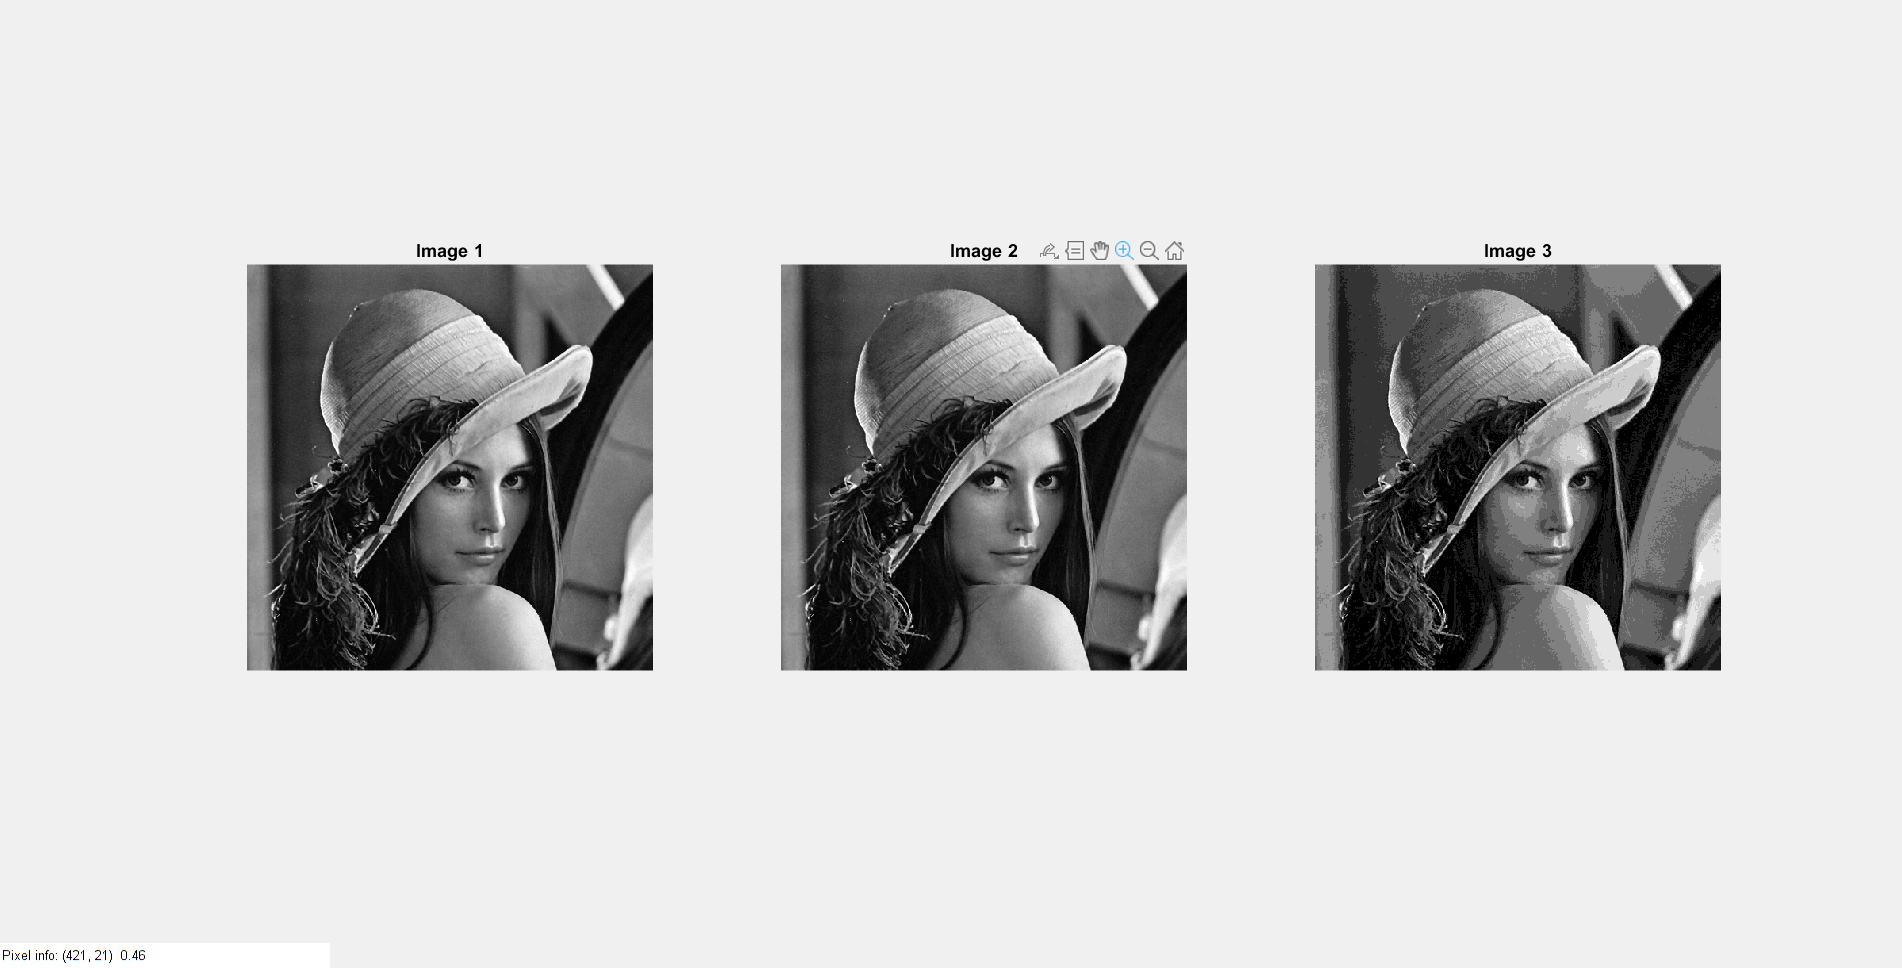

N = 4; % Uncomment and define N

ima_uniform  = Uniform_Quantizer (ima,N);  
ima_maxlloyd = MaxLloyd_Quantizer(ima,N); 

Histogram(ima, ima_uniform, ima_maxlloyd); 

Comment on the differences you perceive `in these two quantized images. `

- Comments:

- **Uniform Quantization** treats all intensity levels equally, leading to more visible artifacts and less efficient use of quantization levels.

- **Max-Lloyd Quantization** optimizes the quantization process by adapting to the image's intensity distribution, producing higher visual quality and preserving important image details more effectively.

Entropy(ima_uniform)
Entropy(ima_maxlloyd) 


mse_image(ima,ima_uniform)  

N = 2

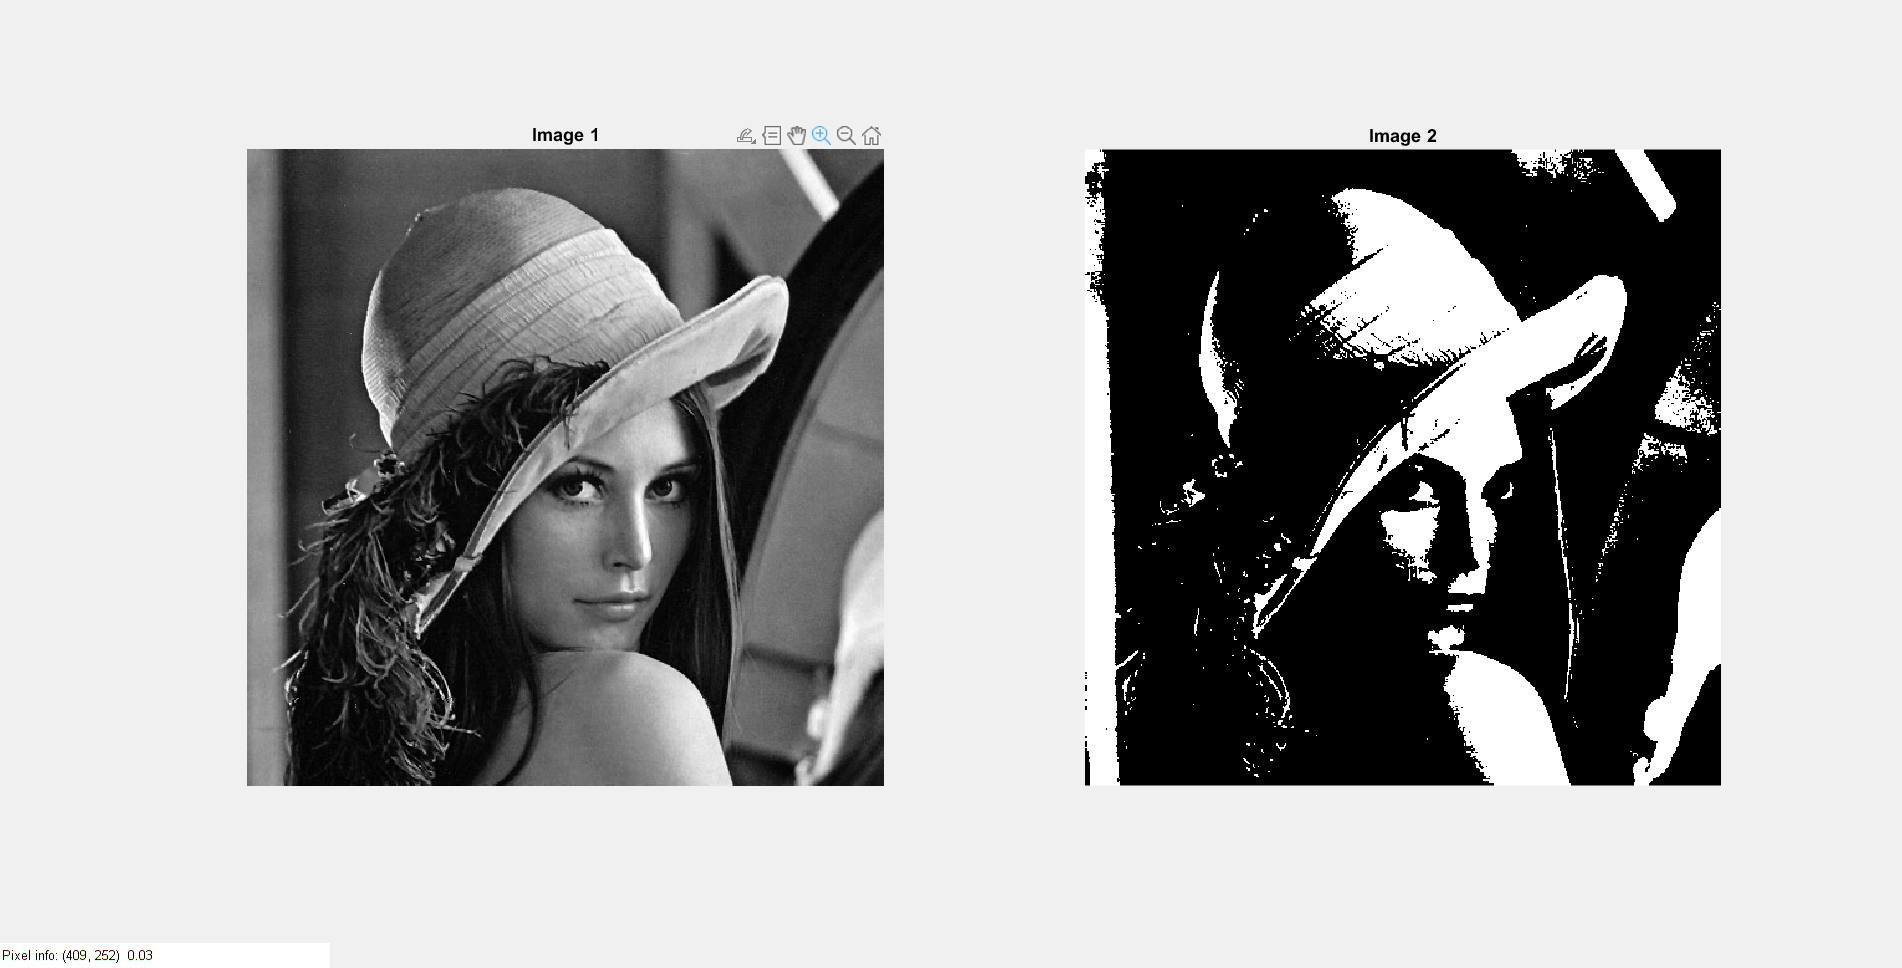

psnr_image(ima,ima_uniform)  
ssim(ima,ima_uniform)  

ans = 5.3012

ans = 3.1732

ans = 0.7940

ans = 8.8248e-04

ans = 30.5429

ans = 0.7771

ans = 0.0811

ans = 10.9109

ans = 0.1498

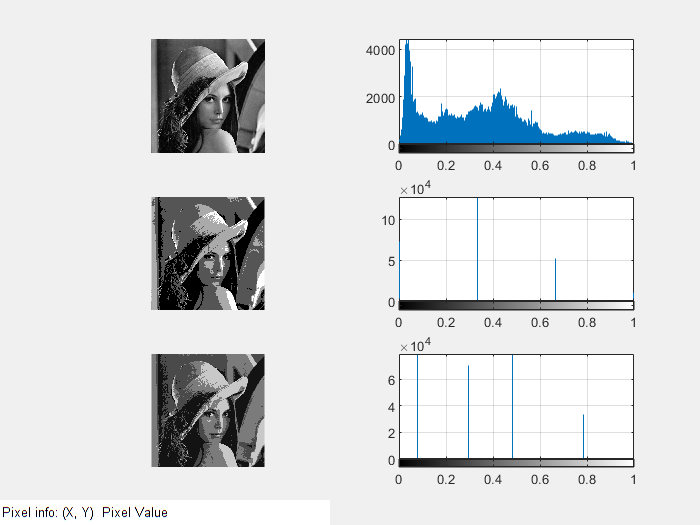

ans = 1.6692

ans = 1.9336

ans = 0.0088

ans = 20.5736

ans = 0.5160

ans = 0.0039

ans = 24.0655

ans = 0.6904

mse_image(ima,ima_maxlloyd)  
psnr_image(ima,ima_maxlloyd)  
ssim(ima,ima_maxlloyd)  

Comment on the differences in terms of these objective measures`. `

- Comments:

- **Entropy**: Max-Lloyd quantization results in slightly higher entropy compared to uniform quantization because it more efficiently distributes the gray levels, retaining more useful information.

- **MSE**: Max-Lloyd quantization has a lower MSE, indicating it introduces less quantization error and better preserves the original pixel values.

- **PSNR**: Max-Lloyd quantization yields a higher PSNR, reflecting better image quality and less perceptible noise or distortion.

- **SSIM**: Max-Lloyd quantization has a higher SSIM, meaning it better preserves the structure and perceptual quality of the original image compared to uniform quantization.

Overall, Max-Lloyd quantization is a more efficient and adaptive method that provides better objective measures (entropy, MSE, PSNR, SSIM) than uniform quantization.